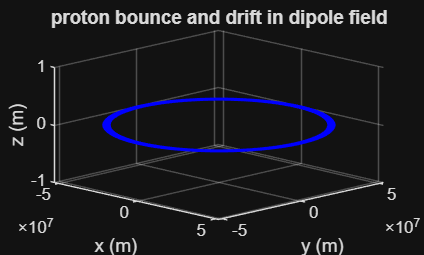

% now we use a dipole magnetic field instead of a uniform one (Earth)
% what does this mean physically?
% near the equator the field points northward (z)
% near the poles it gets stronger and bends toward Earth
% a charged particle gets trapped, it bounces back and forth between the
% poles (bounce motion) while also drifting around Earth (drift motion)

% define physical constants
q = 1.6e-19; % charge of a proton in coulombs
m = 1.67e-27; % mass of proton in kg
re = 6371000; % Earth's radius in m
b0 = 31000e-9 * re^3; % dipole moment constant
v0 = 9500000; % new speed m/s

%% the dipole field strength at any distance r from Earth's center is b = b0 / r^3
b_at_start = b0 / (8*re)^3;

omega = (q * b_at_start) / m; % gyrofrequency equation, shows how fast the proton spins

t_gyro = (2 * pi) / omega; % calculate period of one full gyration/circle

dt = t_gyro / 5000; % time step between each step of RK4 integrator 
%% updated to 5000 

n = 5000 * 1000; % number of time steps simulation will run for (5000 full circles worth of time, 1000 steps per circle)

t = zeros(1, n+1); % creates a row of n + 1 zeros in a row, time axis of simulation
x = zeros(1, n+1); % same thing but store the x position of the proton at every moment in time 
y = zeros(1, n+1); % same but y position
z = zeros(1, n+1); % same but z position
vx = zeros(1, n+1); % stores x component of proton's velocity at every moment
vy = zeros(1, n+1); % same but y component
vz = zeros(1, n+1); % same but z component

% set initial conditions
x(1) = 8 * re; % initial x position
%% updated to start at 8 times the Earth's radius
y(1) = 0; % initial y position
z(1) = 0; % initial z position
vx(1) = v0; % initial x velocity
vy(1) = 0; % initial y velocity
vz(1) = 0; % initial z velocity

% RK4 time loop

for i = 1:n
    state = [x(i); y(i); z(i); vx(i); vy(i); vz(i)]; % state vector
    k1 = dt * lorentz(state, q, m, b0); % estimated change in all six quantities in one full time step 
    k2 = dt * lorentz(state + 0.5*k1, q, m, b0); % add half of the estimated change
    k3 = dt * lorentz(state + 0.5*k2, q, m, b0); % add half of the second estimated change
    k4 = dt * lorentz(state + k3, q, m, b0); % estimate change using the full third step
    new_state = state + (1/6) * (k1 + 2*k2 + 2*k3 + k4); % complete updated position and velo one time step later
    % new state = state + 1/6(k1 + 2k2 + 2k3 + k4) from Simpson's rule 

    x(i+1) = new_state(1); % take 1st value out of new_state and store in slot i+1 of the x array
    y(i+1) = new_state(2); % take 2nd value (y) " "
    z(i+1) = new_state(3); 
    vx(i+1) = new_state(4);
    vy(i+1) = new_state(5);
    vz(i+1) = new_state(6);
    t(i+1) = t(i) + dt; % takes current time stored in slot i and adds one dt to it
end

% plot results


figure;


plot3(x, y, z, 'b-');
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title('proton bounce and drift in dipole field');
grid on;
view(45, 25);

saveas(gcf, 'figures/gyro2c.1.png')

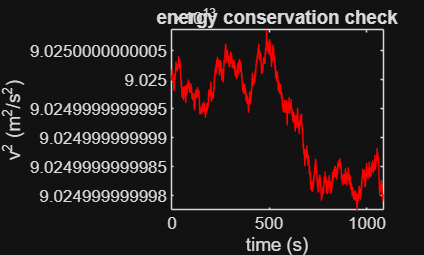



energy = vx.^2 + vy.^2 + vz.^2;
figure;
plot(t, energy, 'r-');
xlabel('time (s)');
ylabel('v^2 (m^2/s^2)');
title('energy conservation check');

saveas(gcf, 'figures/gyro2c.2.png')


fprintf('the energy is oscillating because the proton is bouncing back and forth between regions of different field strengths');

the energy is oscillating because the proton is bouncing back and forth between regions of different field strengths

%% it also goes down with time because of the error in the numerical method

function dstate = lorentz(state, q, m, b0) % dstate = [dx/dt, dy/dt, dz/dt, dvx/dt, dvy/dt, dvz/dt]
    dstate = zeros(6,1); % output variable to fill w/ derivatives

    %% we extract x, y, z from the state vector because the magnetic field is no longer uniform and the field strength and direction now depend on position
    x = state(1);
    y = state(2);
    z = state(3);
    vx = state(4);
    vy = state(5);
    vz = state(6);


    r = sqrt(x^2 + y^2 + z^2);

%% equations for magnetic field of origin centered dipole in cartesian
    bx = b0 * (3*x*z) / r^5;
    by = b0 * (3*y*z) / r^5;
    bz = b0 * (3*z^2 - r^2) / r^5;

    dstate(1) = vx;
    dstate(2) = vy;
    dstate(3) = vz;
    dstate(4) = (q/m) * (vy*bz - vz*by);
    dstate(5) = (q/m) * (vz*bx - vx*bz);
    dstate(6) = (q/m) * (vx*by - vy*bx);


end

